LII Model Parameters Based on Lemaire et al.

% Laser-Induced Incandescence (LII) Model
%
% Based on:
% Lemaire, R., Menanteau, S. (2021)
% "Modeling laser-induced incandescence of Diesel soot"
% Applied Physics B, 127:138
% https://doi.org/10.1007/s00340-021-07665-y
%
% This implementation reproduces the base model from the paper.
% No experimental CERL data is included in this repository.

clear; clc;
params.c = 2.998e10; % Speed of Light [cm/s] (Lemaire 2021, Appendix)
params.e_charge = 1.60218e-19; % Electron charge [C] (Lemaire 2021, Appendix)

% Diffusion constants
params.A0_C2 = 9.0235e-4; % [W*cm^-1*K^-1] (Lemaire 2021, Appendix)
params.A0_C3 = 5.7683e-4; % [W*cm^-1*K^-1](Lemaire 2021, Appendix)
params.A1_C2 = 3.8475e-7; % [W*cm^-1*K^-2](Lemaire 2021, Appendix)
params.A1_C3 = 1.8429e-7; % [W*cm^-1*K^-2](Lemaire 2021, Appendix)

params.Bj = NaN; % Sublimation parameter [bar]

% Saturation coefficients
params.B_lambda1_a= NaN; % annealed soot
params.B_lambda1_s= NaN; % unannealed soot
params.B_lambda_n_a= NaN; % annealed
params.B_lambda_n_s= NaN; % unannealed

params.c_a= NaN;   % Annealed soot [J/(g*K)]
params.c_s= NaN;  % Unannealed soot [J/(g*K)]
params.Cabs_multi_a= NaN;   % [cm^2] 
params.Cabs_multi_s= NaN;   % [cm^2]

% Heat capacities
params.Cp_CO= NaN; % Molar heat capacity of CO [J/mol/K]
params.Cp_m= NaN; % Temperature-dependent molar heat capacity [J/mol/K]
params.Cp_O2= NaN; % Molar heat capacity of O2 [J/mol/K]

% Diffusion
params.D_eff= NaN; % Total effective diffusion constant [cm^2/s]
params.D_eff_Cj= NaN; % Effective diffusion constant of Cj clusters [cm^2/s]
params.Dh = @(a) 1.99345 + 0.30224*a - 0.11276*a.^2; % Scaling factor(Lemaire 2021, Appendix)

params.D_HC= NaN;  % Equivalent heat conduction diameter [cm]
params.Dp= NaN; % Primary particle diameter [cm]
params.Dp_ref = 34e-7; % Reference diameter [cm](Lemaire 2021, Appendix)

params.E_m= NaN; % Refractive index function (unannealed)
params.Ea_m= NaN; % Refractive index function (annealed)

params.f= NaN; % Eucken correction factor

params.f1_a= NaN; % Linear absorption scaling (annealed)
params.f1_s= NaN; % Linear absorption scaling (unannealed)

params.fa= NaN; % Absorption empirical scaling (annealed soot)
params.exp= NaN; % Experimental data placeholder
params.F= NaN; % Laser fluence [J/cm^2]

params.hNp= NaN; % Correction factor for multiple scattering
params.hNp_inf= NaN; % Asymptotic correction (large aggregates)
params.J= NaN; % Partial pressure function of Cj clusters

params.ka = @(Tp) 4.935e23 .* exp(-1.255e5 ./ (8.314 .* Tp)); % A-site oxidation [s^-1*cm^-2*bar^-1](Lemaire 2021, Appendix)
params.kb = @(Tp) 4.935e21 .* exp(-6.352e4 ./ (8.314 .* Tp)); % B-site oxidation [s^-1*cm^-2*bar^-1](Lemaire 2021, Appendix)

params.kB = 1.381e-23; % Boltzmann constant [J/K]
params.kdiss = @(Tp) 1e18 .* exp(-9.6e5 ./ (8.314 .* Tp)); % pyrolysis rate constant [s^-1](Lemaire 2021, Appendix)

params.kg = @(Tg) 1.0811e-4 + 5.1519e-7 .* Tg;   % [W/cm/K] Thermal Conductivity(Lemaire 2021, Appendix)
params.kh = @(a) 1.04476 + 0.22329*a + 7.14286e-3*a.^2; % Scaling factor for D_HC(Lemaire 2021, Appendix)
params.kim = @(Tp) 1e8 .* exp(-8.3e4 ./ (8.314 .* Tp));   % Interstitial Migration [s^-1](Lemaire 2021, Appendix)

params.kox_a= NaN; % Annealed soot oxidation rate [s^-1*cm^-2]
params.kox_s= NaN; % Unannealed soot oxidation rate [s^-1*cm^-2]
params.kp = 1.38065e-22; % Boltzmann constant in bar*cm^3/K(Lemaire 2021, Appendix)
params.kt = @(Tp) 3.79e27 .* exp(-4.06e5 ./ (8.314 .* Tp)); % Site Transformation [s^-1*cm^-2](Lemaire 2021, Appendix)
params.kvmig = @(Tp) 1.5e17 .* exp(-6.7e5 ./ (8.314 .* Tp)); % Vacancy Migration [s^-1](Lemaire 2021, Appendix)

params.kz = @(Tp) 21.02 .* exp(1.713e4 ./ (8.314 .* Tp)); % Oxide formation [bar^-1](Lemaire 2021, Appendix)
params.k_lambdan_a= NaN; % removal rate of C2 from annealed soot [s^-1]
params.k_lambdan_s= NaN; % removal rate of C2 from unannealed soot [s^-1]
params.me = 9.1095e-35; % electron mass [J*s^2*cm^-2](Lemaire 2021, Appendix)
params.Mg= NaN; % average mass of gas molecules [g]
params.Mp= NaN; % primary particle mass [g]
params.n= NaN; % number of photons absorbed (dimensionless)
params.NA = 6.02214e23; % Avogadro number [mol^-1](Lemaire 2021, Appendix)
params.Nc= NaN; % number of atoms in primary particle
params.Nd= NaN; % number of lattice defects
params.Np= NaN; % number of primary particles per aggregate
params.Ns_a = 3.8e15; % density of carbon atoms (annealed) [cm^-2](Lemaire 2021, Appendix)
params.Ns_s = 2.8e15; % density of carbon atoms (unannealed) [cm^-2](Lemaire 2021, Appendix)
params.Ntot= NaN; % aggregate number density
params.p_Dp= NaN; % PDF of primary particle size
params.p_Np= NaN; % PDF of aggregate size
params.Pdiss= NaN; % effective pressure from photodesorption

params.Peq_Cj= NaN; % thermal equilibrium partial pressure [bar]

params.Pg= NaN; % ambient pressure [bar]
params.PO2 = @(Pg) 0.21*Pg; % O2 partial pressure [bar](Lemaire 2021, Appendix)

params.Pphot= NaN; % instantaneous pressure from photodesorption

params.Pref = 1.01325; % reference pressure [bar](Lemaire 2021, Appendix)

params.Psat_Cj= NaN; % saturation pressure of Cj clusters
params.Psurf_Cj= NaN;% surface pressure of Cj

params.P_lambda_a= NaN;  % effective pressure (annealed soot)
params.P_lambda_s= NaN;  % effective pressure (unannealed soot)

params.q_exp= NaN; % normalized laser irradiance

params.Qabs= NaN; % absorption [W]
params.Qann= NaN; % annealing [W]
params.Qcond_C= NaN; % conduction (continuum) [W]
params.Qcond_FM= NaN; % conduction (free molecular) [W]
params.Qox= NaN; % oxidation [W]
params.Qrad= NaN; % radiation [W]
params.Qsub= NaN; % sublimation [W]
params.Qth= NaN; % thermionic emission [W]

params.R = 8.3145; % universal gas constant [J/mol/K](Lemaire 2021, Appendix)
params.Rdet= NaN; % spectral response of detection system

% Gas constants
params.Rm = 8.3145e7; % [erg*cm^-2*mol^-1*K^-1](Lemaire 2021, Appendix)
params.Rp = 83.145; % [bar*cm^3*mol^-1*K^-1](Lemaire 2021, Appendix)
params.S_LII= NaN; % LII signal [a.u.]

params.t= NaN; % time [s]
params.t_l= NaN; % laser pulse duration [s]
params.T_f_CO = 790; % temperature where CO molecules emit [K](Lemaire 2021, Appendix)
params.Tg= NaN; % ambient gas temperature [K]
params.Tp= NaN; % particle temperature [K]
params.Tref = 0; % reference temperature [K](Lemaire 2021, Appendix)
% Given values: (Lemaire 2021, Appendix)
params.Tc_C1 = 4603.48;
params.Tc_C2 = 4456.59;
params.Tc_C3 = 4136.78;
params.Tc_C4 = 4949.74;
params.Tc_C5 = 4772.87;
params.T_delta= NaN; % limiting sphere temperature (Fuchs model)
params.Uint= NaN;    % internal energy of soot particles [J]
params.Wj = 12.01;   % species weight (C clusters) per j [g/mol](Lemaire 2021, Appendix)
params.WO2 = 31.99; % oxygen molecular weight [g/mol](Lemaire 2021, Appendix)
params.Xa= NaN; % annealed fraction
params.Xd= 1e-2; % defect density (initial)(Lemaire 2021, Appendix)

params.Zox= NaN; % collision rate of O2 with soot surface [s^-1*cm^-2]

% Multi scattering parameters
params.a1= NaN; % parameter for hNp
params.a2= NaN;
params.a3= NaN;

params.alpha_T= NaN; % thermal accommodation coefficient
params.gamma = @(Cp_m) Cp_m ./ (Cp_m - params.R); % Cp/(Cp - R)(Lemaire 2021, Appendix)

params.gamma_j= NaN; % for desorbing species Cj
params.gamma_star= NaN; % mean heat capacity ratio
params.delta= NaN;  % distance between particle and limiting sphere [cm]

% Formation by thermal Sublimation enthalpy
params.dH_sub = @(Tp) -12.326 .* Tp + 8.545e5;   % [J/mol](Lemaire 2021, Appendix)

% Interstitial migration
params.dH_mig = -1.9e4;   % [J/mol](Lemaire 2021, Appendix)

% Vapor species formation enthalpies (C1–C5) (Lemaire 2021, Appendix)
params.dH_C1 = @(Tp) -5.111 .* Tp + 7.266e5;
params.dH_C2 = @(Tp) -12.326 .* Tp + 8.545e5;
params.dH_C3 = @(Tp) -26.921 .* Tp + 8.443e5;
params.dH_C4 = @(Tp) -2.114e-3 .* Tp.^2 - 7.787 .* Tp + 9.811e5;
params.dH_C5 = @(Tp) -2.598e-3 .* Tp.^2 - 7.069 .* Tp + 9.898e5;

% Oxidation enthalpy (Lemaire 2021, Appendix)
params.dH_ox = @(Tp) 2.8901e-14 .* Tp.^5 - 4.9868e-10 .* Tp.^4 + 3.3206e-6 .* Tp.^3 - 1.0307e-2 .* Tp.^2 + 7.9303 .* Tp - 1.1221e5;

% Vacancy migration (Lemaire 2021, Appendix)
params.dH_vmig = -1.4e5; % [J/mol]
% Photodesorption enthalpies
params.dH_lambdan_a = 3.4e5; % annealed soot [J/mol](Lemaire 2021, Appendix)
params.dH_lambdan_s= NaN; % unannealed soot [J/mol] (not given)

params.lambda_det= NaN; % spectral detection range [cm]
params.delta_phi= NaN; % positive charge buildup
params.eta= NaN; % stoichiometric coefficient
params.lambda= NaN; % wavelength [cm]
params.lambda0 = 1; % arbitrary wavelength [cm](Lemaire 2021, Appendix)
params.lambda_c= NaN; % upper boundary wavelength [cm]
params.lambda_l= NaN; % laser excitation wavelength [cm]
params.lambda_g= NaN; % mean free path of gas molecules [cm]
params.lambda_delta= NaN; % mean free path inside limiting sphere [cm]
params.nabla1= NaN;   % function used in Fuchs model
params.nabla2= NaN;   % function used in Fuchs model

params.xi= NaN; % dimensionless parameter for pressure calculation
% Annealed soot density
params.rho_a = @(Tp) 2.6 - 1e-4 .* Tp; % [g/cm^3](Lemaire 2021, Appendix)

% Unannealed soot density
params.rho_s = @(Tp) 2.3031 - 7.3106e-5 .* Tp; % [g/cm^3](Lemaire 2021, Appendix)
params.sigma_j= NaN;  % molecular cross section of sublimed species [cm^2]

params.sigma_n_a= NaN; % cross section for photodesorption (annealed)
params.sigma_n_s= NaN; % cross section for photodesorption (unannealed)
params.phi = 7.37e-19; % [J](Lemaire 2021, Appendix)
params.XA= NaN; % fraction of available A sites
params.Qexp= NaN; % laser spatial domain [cm^2]

Qabs based on Appendix 1 - Lemaire 2021

h = 6.626e-34;
params.Dp = 16.4e-7; % cm
params.Np = 1; % assumption as suggested
params.Tg = 1850; % K
params.lambda_l = 1064e-7; % cm
params.F = 0.2; % J/cm^2 laser fluence
params.t_l = 8e-9; % s pulse duration (Bladh 2008)
params.Xa = 0; % no annealing
params.E_m = 0.23; % refractive index function
params.Ea_m = 0.23; % placeholder since Xa=0
params.B_lambda1_s = 1.15; % J/cm^2 saturation coefficient
params.B_lambda1_a = 1.15; % placeholder
params.hNp = NaN; % calculated later
params.n = 2; % two photon process
params.c_s = 2.1;  % J/g/K (Bladh 2004)
params.c_a = 2.1;  % J/g/K
params.rho_s = @(Tp) (2.3031 - 7.3106e-5 .* Tp); % g/cm^3
params.rho_a = @(Tp) (2.6 - 1e-4 .* Tp); % g/cm^3
params.c = 2.998e10; % cm/s
params.kB = 1.381e-23; % J/K
params.R = 8.3145; % J/mol/K
params.Ntot = 1e8; % cm^-3 assumption
params.Dp_ref = 34e-7; % cm
params.lambda0 = 1; % cm
c = params.c;

% Unknown parameters:
params.fa = 1;
params.f1_a = 1;
params.f1_s = 1;

Dp   = params.Dp;
lambda_l = params.lambda_l;
F    = params.F;
tl   = params.t_l;

Gaussian temporal profile. I shifted the profile to 3tl. The profile is normalized as well.

t0 = 1.5 * tl;
q_exp = @(t) exp(-4*log(2)*((t - t0)/tl).^2);
t_test = linspace(0,6*tl,1000);
norm_q = trapz(t_test, q_exp(t_test));
q_exp_norm = @(t) q_exp(t) ./ norm_q;
I = @(t) F .* q_exp_norm(t);


Setup of equations for Qdot_abs, based on equations in Lemaire 2021

Np   = params.Np;
Ntot = params.Ntot;
pNp  = params.p_Np;
pNp = 1;
Xa   = params.Xa;
Em   = params.E_m;
Ea_m = params.Ea_m;
fa   = params.fa;
B1s = params.B_lambda1_s;
B1a = params.B_lambda1_a;
f1s = params.f1_s;
f1a = params.f1_a;
hNp = params.hNp;
n  = params.n;
k_ls = params.k_lambdan_s;
k_la = params.k_lambdan_a;
Nss = params.Ns_s;
Nsa = params.Ns_a;
B_lambdan_s = 0.41; % J cm^-2 Lemaire 2021
B_lambdan_a = 0.41; % J cm^-2 assumption same as unannealed
sigma_lambdan_s = 4.2e-10; % n=2
sigma_lambdan_a = 4.2e-10;

alpha1_prime = (1.0209 - 24.0657.*(log((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp))./((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp))) + 2244.37 * (((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp)).^(-1.5))).^(-1);
alpha2_prime = (0.9871 +2.4878.*(log((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp))./((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp)))).^(-1);
hinfNp = 1.11 * alpha1_prime.^2 * Np.^(2*(alpha2_prime - 1));
hNp = hinfNp + (1 - hinfNp) * exp(-(2/3) * (Np -1).^(0.5));
qn_test = q_exp_norm(t_test).^n;
norm_qn = trapz(t_test, qn_test);
k_ls = @(t) (1 - Xa) .* (lambda_l ./ (n .* h .* c)) .* ((sigma_lambdan_s .* pi .* Dp.^3 .* Nss) ./ 6) .* (B_lambdan_s.^(-n)) .*(1 ./ norm_qn) .* (1 - exp(-((I(t) ./ B_lambdan_s).^n)));
k_la = @(t) Xa .*(lambda_l ./ (n .* h .* c)) .*((sigma_lambdan_a .* pi .* Dp.^3 .* Nsa) ./ 6) .*(B_lambdan_a.^(-n)) .* (1 ./ norm_qn) .* (1 - exp( -((I(t) ./ B_lambdan_a).^n)));
Cabs_multi_s =  (1 - Xa) * (pi^2 * Dp^3 / lambda_l) * Em * hNp * Np * pNp;
Cabs_multi_a =  Xa * (pi^2 * Dp^3 / lambda_l) * fa * Ea_m * hNp * Np * pNp;

Qdot_abs = @(t) Cabs_multi_s.*f1s.*(B1s./norm_q).*(1-exp(-(F*q_exp(t))./B1s)) + Cabs_multi_a.*f1a.*(B1a./norm_q).*(1-exp(-(F*q_exp(t))./B1a)) + Np.*n.*(h*c/lambda_l).*(k_ls(t)+k_la(t));

Just plotting the Gaussian

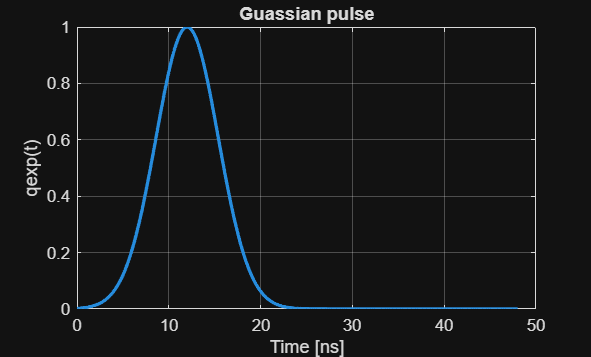

figure
plot(t_test*1e9, q_exp(t_test), 'LineWidth', 2)

xlabel('Time [ns]')
ylabel('qexp(t)')
title('Guassian pulse')

grid on

Now we will implement the radiation equations

lambda_rad = linspace(200e-7,5000e-7,4000);
Qdot_rad = @(Tp) 8 .* pi .* h .* c.^2 .* trapz( lambda_rad, ((Cabs_multi_s + Cabs_multi_a) ./ (lambda_rad.^5)) .* ( (1 ./ (exp((h.*c) ./ (lambda_rad .* params.kB .* Tp)) - 1)) - (1 ./ (exp((h.*c) ./ (lambda_rad .* params.kB .* params.Tg)) - 1)) ));
Qrad_3500 = Qdot_rad(3500);
disp(Qrad_3500)

   2.9155e-10



Now we will implement conduction free molecular

gamma_star = 1.4; % assumption
params.alpha_T = 0.49; % Lemaire 2021
params.Pg = 1.01325; % assumption [bar]
params.Mg = 29; % g/mol assumption
Tdelta = @(Tp)params.Tg; % assumption

if Np == 1
    DHC = Dp;
else 
    DHC = Dp * (Np/params.kh(params.alpha_T)) ^ (1/params.Dh(params.alpha_T));
end

Qcond_FM = @(Tp) (1/8) .* pi .* params.alpha_T .* DHC.^2 .* params.Pg .* sqrt((8 .* params.kp .* Tdelta(Tp)) ./ (pi .* params.Mg)) .* ((gamma_star + 1) ./ (gamma_star - 1)) .* ((Tp ./ Tdelta(Tp)) - 1);
Qcond_FM(3500)

ans = 4.2026e-22

Now we will implement the continuum conduction equation

kg = @(T) (1.0811e-4 + 5.1519e-7 .* T); % W/cm/K
gamma_g = 1.4; % assumption
f_eucken = 1.9; % assumption
lambda_g = (kg(params.Tg) ./ (f_eucken .* params.Pg)) .* (gamma_g - 1) .* sqrt((pi .* params.Mg .* params.Tg) ./ (2 .* params.kp));
lambda_delta = @(Tp) max( (kg(Tdelta(Tp)) .* sqrt(Tdelta(Tp)) ./ (kg(params.Tg) .* sqrt(params.Tg))) .* lambda_g, 1e-12);
Tp_test = 4000;

delta_solver = @(Tp) safe_delta(Tp,DHC,lambda_delta);

function delta = safe_delta(Tp,DHC,lambda_delta)

ld = lambda_delta(Tp);

f = @(delta) lhs_rhs(delta,Tp,DHC,ld);

try
    delta = fzero(f,[1e-12 1e-4]);
catch
    delta = ld;
end

end
function val = lhs_rhs(delta,Tp,DHC,lambda_d)

Lambda1 = 1 + (2*lambda_d/DHC);
Lambda2 = 1 + (2*lambda_d/DHC)^2;

lhs = (2*delta + DHC)/DHC;
rhs = (DHC^2)/(4*lambda_d^2) * ( (1/5)*Lambda1^5 - (1/3)*Lambda2*Lambda1^3 + (2/15)*Lambda2^(5/2) );
val = lhs - rhs;
end
a = 1.0811e-4;
b = 5.1519e-7;

Qcond_C = @(Tp) 4*pi*(DHC/2 + delta_solver(Tp)) .* ( a*(Tdelta(Tp) - params.Tg) + 0.5*b*(Tdelta(Tp).^2 - params.Tg^2));
Qcond_C(3500)

ans = 0

Now we will consider oxidation equations

CpCO = 29.14; % J/mol/K assumption
CpO2 = 29.36; % J/mol/K assumption
Po2 = 0.21 * params.Pg;
chiA = @(Tp) 1 ./ (1 + (params.kt(Tp) ./ (params.kb(Tp) * Po2)));
Zox = (Po2 ./ (params.kp * params.Tg)) * sqrt((params.Rm * params.Tg) ./ (2 * pi * params.WO2));
kox_a = @(Tp)(2.8 * Zox ./ sqrt(params.Tg)) * exp(-1.4e5 ./ (params.R * Tp)) * params.Xa;
kox_s = @(Tp)12 * Po2 * (((params.ka(Tp) * chiA(Tp))./ (1 + params.kz(Tp) * Po2)) + params.kb(Tp) * (1 - chiA(Tp))) * (1 - params.Xa);
dMpdt = @(Tp)(-2 * pi * (params.Dp)^2 * 12.011 * (kox_a(Tp) + kox_s(Tp)))./ (params.NA);
Hox_term = @(Tp) ((CpCO .* (params.T_f_CO - params.Tref))-0.5 .* (CpO2 .* (params.Tg - params.Tref)) + (params.R/2) .* (params.T_f_CO - params.Tg) + params.dH_ox(Tp));

Qox = @(Tp)params.Np * (1 ./ 12.011) * Hox_term(Tp) * dMpdt(Tp);
Qox(3500)

ans = 5.5008e-09

Now for thermionic emissions

phi = params.phi;
me = params.me;
Qth = @(Tp) params.Np .* ((4 .* phi .* me .* (pi .* params.Dp .* params.kB .* Tp).^2) ./ (h.^3)) .* exp(-phi ./ (params.kB .* Tp));
Qth(3500)

ans = 1.3670e-08

To implement annealing equations

params.Nc = (pi/6) * params.Dp^3 * params.rho_s(params.Tg) * params.NA / 12.011;

params.Nd = params.Xd * params.Nc;

Xa_fun = @(Nd) 1 - (Nd ./ (params.Xd * params.Nc));
dNddt = @(Tp,Nd) Xa_fun(Nd) .* (params.Nc/2) .* params.kdiss(Tp) - params.kim(Tp) .* Nd - params.kvmig(Tp) .* Nd;

Qann = @(Tp,Nd) params.Np .*  ( (-params.dH_mig .* params.kim(Tp) .* Nd) - (params.dH_vmig .* params.kvmig(Tp) .* Nd)) ./ params.NA;

Now to implement sublimation equations

params.f = (9 * 1.4 - 5) / 4;
sigma_2 = 2.4e-15; % cm^-2 (Michelsen 2003)
sigma_3 = 4.5e-15; % cm^-2 (Michelsen 2003)
Deff_C2 = @(Tp) (3 .* params.f .* params.kp .* Tp ./ (4 * sigma_2 * params.Pg)) * sqrt(params.Rm / (pi * 12.011 * 2)) * ((Tp + params.A0_C2/params.A1_C2) ^ 2 - (params.Tg + params.A0_C2/params.A1_C2) ^ 2) / ((sqrt(Tp) * (Tp + 3 * params.A0_C2/params.A1_C2)) - sqrt(params.Tg) * (params.Tg + 3 * params.A0_C2/params.A1_C2));
Deff_C3 = @(Tp) (3 .* params.f .* params.kp .* Tp ./ (4 * sigma_3 * params.Pg)) * sqrt(params.Rm / (pi * 12.011 * 3)) * ((Tp + params.A0_C3/params.A1_C3) ^ 2 - (params.Tg + params.A0_C3/params.A1_C3) ^ 2) / ((sqrt(Tp) * (Tp + 3 * params.A0_C3/params.A1_C3)) - sqrt(params.Tg) * (params.Tg + 3 * params.A0_C3/params.A1_C3));
Deff = @(Tp) Deff_C3(Tp) * (1 - params.Xa) + Deff_C2(Tp) * params.Xa;



To solve the ODE, in this we consider the equation dU/dt = Qdot_abs and then simplifying that with respect to the equations given in Lemaire 2021.

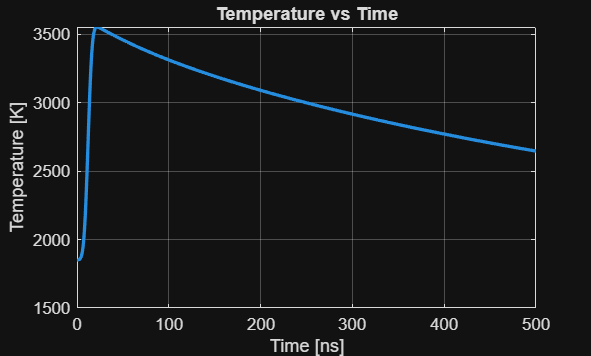

T0 = params.Tg;
rho_s = params.rho_s(T0);
rho_a = params.rho_a(T0);
c_s = params.c_s;
c_a = params.c_a;

tspan = [0 500e-9];

opts = odeset('RelTol',1e-6,'AbsTol',1e-6);

Nc0 = ...
(pi/6) .* ...
params.Dp.^3 .* ...
params.rho_s(params.Tg) .* ...
params.NA ./ ...
12.011;

Nd0 = params.Xd .* Nc0;

Y0 = [params.Tg;
      params.Dp;
      Nd0];

[t,Y] = ode15s(@(t,Y) LII_odes(t,Y,params), tspan, Y0, opts);

Tp = Y(:,1);
Dp = Y(:,2);
Nd = Y(:,3);

function dYdt = LII_odes(t,Y,params)

Tp = Y(1);
Dp = Y(2);
Nd = Y(3);


h = 6.626e-34;

Np = params.Np;

lambda_l = params.lambda_l;
F = params.F;
n = params.n;

Em = params.E_m;
Ea_m = params.Ea_m;

fa = params.fa;

f1s = params.f1_s;
f1a = params.f1_a;

B1s = params.B_lambda1_s;
B1a = params.B_lambda1_a;

Nss = params.Ns_s;
Nsa = params.Ns_a;

c = params.c;
rho_s = params.rho_s(Tp);
rho_a = params.rho_a(Tp);

Nc = ...
(pi/6) .* ...
Dp.^3 .* ...
rho_s .* ...
params.NA ./ ...
12.011;

Xa = ...
1 - ...
(Nd ./ ...
(params.Xd .* Nc));

Xa = max(0,min(1,Xa));

rho_eff = ...
rho_s .* (1 - Xa) ...
+ rho_a .* Xa;

Cp_eff = ...
params.c_s .* (1 - Xa) ...
+ params.c_a .* Xa;

tl = params.t_l;

t0 = 1.5 * tl;

q_exp = @(t) exp(-4*log(2)*((t - t0)/tl).^2);

t_test = linspace(0,6*tl,1000);

norm_q = trapz(t_test,q_exp(t_test));

q_exp_norm = @(t) q_exp(t)./norm_q;

I = @(t) F .* q_exp_norm(t);

alpha1_prime = (1.0209 - 24.0657 .* (log((lambda_l.*params.Dp_ref)./(params.lambda0 .* Dp)) ./ ((lambda_l.*params.Dp_ref)./(params.lambda0 .* Dp))) + 2244.37 .* (((lambda_l.*params.Dp_ref)./(params.lambda0 .* Dp)).^(-1.5))) .^(-1);

alpha2_prime = (0.9871 + 2.4878 .* (log((lambda_l.*params.Dp_ref)./(params.lambda0 .* Dp)) ./ ((lambda_l.*params.Dp_ref)./(params.lambda0 .* Dp)))) .^(-1);

hinfNp = 1.11 .* alpha1_prime.^2 .* Np.^(2 .* (alpha2_prime - 1));

hNp = hinfNp + (1 - hinfNp) .* exp(-(2/3) .* (Np -1).^(0.5));

qn_test = q_exp_norm(t_test).^n;

norm_qn = trapz(t_test,qn_test);

B_lambdan_s = 0.41;
B_lambdan_a = 0.41;

sigma_lambdan_s = 4.2e-10;
sigma_lambdan_a = 4.2e-10;

k_ls = (1 - Xa) .* (lambda_l ./ (n .* h .* c)) .* ((sigma_lambdan_s .* pi .* Dp.^3 .* Nss)./6) .* (B_lambdan_s.^(-n)) .* (1 ./ norm_qn) .* (1 - exp(-((I(t)./B_lambdan_s).^n)));

k_la = Xa .* (lambda_l ./ (n .* h .* c)) .* ((sigma_lambdan_a .* pi .* Dp.^3 .* Nsa)./6) .* (B_lambdan_a.^(-n)) .* (1 ./ norm_qn) .* (1 - exp(-((I(t)./B_lambdan_a).^n)));


Cabs_multi_s = ...
(1 - Xa) .* ...
(pi^2 .* Dp.^3 ./ lambda_l) .* ...
Em .* hNp .* Np;

Cabs_multi_a = ...
Xa .* ...
(pi^2 .* Dp.^3 ./ lambda_l) .* ...
fa .* Ea_m .* hNp .* Np;

Qabs = Cabs_multi_s .* f1s .* (B1s./norm_q) .* (1-exp(-(F .* q_exp(t))./B1s)) + Cabs_multi_a .* f1a .* (B1a./norm_q) .* (1-exp(-(F .* q_exp(t))./B1a)) + Np .* n .* (h*c/lambda_l) .* (k_ls + k_la);

CpCO = 29.14;
CpO2 = 29.36;

Po2 = 0.21 * params.Pg;

chiA = @(Tp) ...
1 ./ ...
(1 + (params.kt(Tp) ./ ...
(params.kb(Tp) .* Po2)));

Zox = ...
(Po2 ./ (params.kp .* params.Tg)) .* ...
sqrt((params.Rm .* params.Tg) ./ ...
(2 .* pi .* params.WO2));

kox_a = ...
(2.8 .* Zox ./ sqrt(params.Tg)) .* ...
exp(-1.4e5 ./ (params.R .* Tp)) .* ...
Xa;

term1 = ...
(params.ka(Tp) .* chiA(Tp)) ./ ...
(1 + params.kz(Tp) .* Po2);

term2 = ...
params.kb(Tp) .* ...
(1 - chiA(Tp));

kox_s = ...
12 .* Po2 .* ...
(term1 + term2) .* ...
(1 - Xa);

dMpdt_ox = ...
(-2 .* pi .* Dp.^2 .* 12.011 .* ...
(kox_a + kox_s)) ./ ...
params.NA;

Hox_term = ...
(CpCO .* ...
(params.T_f_CO - params.Tref)) ...
- 0.5 .* ...
(CpO2 .* ...
(params.Tg - params.Tref)) ...
+ (params.R ./ 2) .* ...
(params.T_f_CO - params.Tg) ...
+ params.dH_ox(Tp);

Qox = ...
Np .* ...
(1 ./ 12.011) .* ...
Hox_term .* ...
dMpdt_ox;

lambda_rad = linspace(200e-7,5000e-7,4000);

Qrad = ...
8 .* pi .* h .* c.^2 .* ...
trapz(lambda_rad, ...
((Cabs_multi_s + Cabs_multi_a) ./ ...
(lambda_rad.^5)) .* ...
((1 ./ ...
(exp((h.*c) ./ ...
(lambda_rad .* params.kB .* Tp)) - 1)) ...
- ...
(1 ./ ...
(exp((h.*c) ./ ...
(lambda_rad .* params.kB .* params.Tg)) - 1))));

gamma_star = 1.4;

Tdelta = params.Tg;

if Np == 1

    DHC = Dp;

else

    DHC = ...
    Dp .* ...
    (Np ./ params.kh(params.alpha_T)) ...
    .^ ...
    (1 ./ params.Dh(params.alpha_T));

end

QcondFM = ...
(1/8) .* ...
pi .* ...
params.alpha_T .* ...
DHC.^2 .* ...
params.Pg .* ...
sqrt((8 .* params.kp .* Tdelta) ./ ...
(pi .* params.Mg)) .* ...
((gamma_star + 1) ./ ...
(gamma_star - 1)) .* ...
((Tp ./ Tdelta) - 1);

ka = 0.0012;
lambda_MFP = 0.5665e-4;

G = 22.064;

Ap = pi .* Dp.^2;
QcondFM = ...
2 .* ka .* Ap .* ...
(Tp - params.Tg) ./ ...
(Dp + G .* lambda_MFP);

Nc = ...
(pi/6) .* ...
Dp.^3 .* ...
rho_s .* ...
params.NA ./ ...
12.011;

Xa = ...
1 - ...
(Nd ./ ...
(params.Xd .* Nc));

Xa = max(0,min(1,Xa));

dNddt = ...
Xa .* ...
(Nc./2) .* ...
params.kdiss(Tp) ...
- params.kim(Tp) .* Nd ...
- params.kvmig(Tp) .* Nd;

Qann = ...
Np .* ...
((-params.dH_mig .* ...
params.kim(Tp) .* Nd) ...
- ...
(params.dH_vmig .* ...
params.kvmig(Tp) .* Nd)) ...
./ params.NA;

phi = params.phi;

me = params.me;

Qth = ...
Np .* ...
((4 .* phi .* me .* ...
(pi .* Dp .* params.kB .* Tp).^2) ...
./ (h.^3)) .* ...
exp(-phi ./ ...
(params.kB .* Tp));

Pv = ...
exp( ...
-122.96 ...
+ 9.0558e-2 .* Tp ...
- 2.7637e-5 .* Tp.^2 ...
+ 4.1754e-9 .* Tp.^3 ...
- 2.4875e-13 .* Tp.^4 ...
) .* params.Pg;

Mv = ...
(17.179 ...
+ 6.8654e-4 .* Tp ...
+ 2.9962e-6 .* Tp.^2 ...
- 8.5954e-10 .* Tp.^3 ...
+ 1.0486e-13 .* Tp.^4) ./ 1000;

dHv = ...
2.05398e5 ...
+ 7.3660e2 .* Tp ...
- 0.40713 .* Tp.^2 ...
+ 1.1992e-4 .* Tp.^3 ...
- 1.7946e-8 .* Tp.^4 ...
+ 1.0717e-12 .* Tp.^5;

alpha_m = 0.8;

dMpdt_sub = ...
pi .* Dp.^2 .* ...
alpha_m .* Pv .* ...
sqrt(Mv ./ ...
(2 .* pi .* params.R .* Tp));

Qsub = ...
(dHv .* dMpdt_sub) ./ Mv;

mp = ...
Np .* ...
(pi/6) .* ...
Dp.^3 .* ...
rho_eff;

dTpdt = ...
(Qabs + Qann ...
- Qrad ...
- QcondFM  ...
+ Qox ...
- Qth ...
- Qsub) ...
./ (mp .* Cp_eff);

dMpdt = dMpdt_ox - dMpdt_sub;
dDpdt = ...
(2 ./ ...
(pi .* rho_eff .* Dp.^2)) ...
.* dMpdt;

dYdt = [dTpdt;
        dDpdt;
        dNddt];

end

figure
plot(t*1e9, Tp, 'LineWidth', 2)
xlabel('Time [ns]')
ylabel('Temperature [K]')
title('Temperature vs Time')
grid on

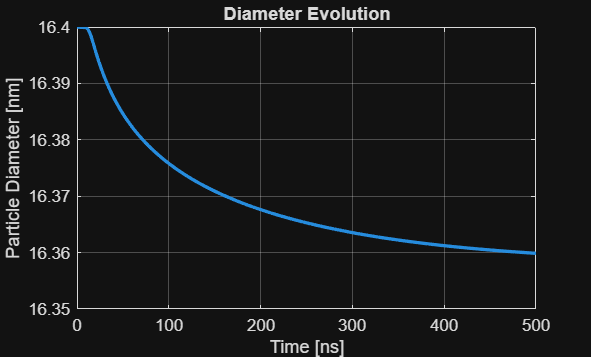

figure
plot(t*1e9, Dp*1e7, 'LineWidth', 2)

xlabel('Time [ns]')
ylabel('Particle Diameter [nm]')
title('Diameter Evolution')

grid on

LII Signal, we use top hat laser profile assumption, so no variation in radial direction.

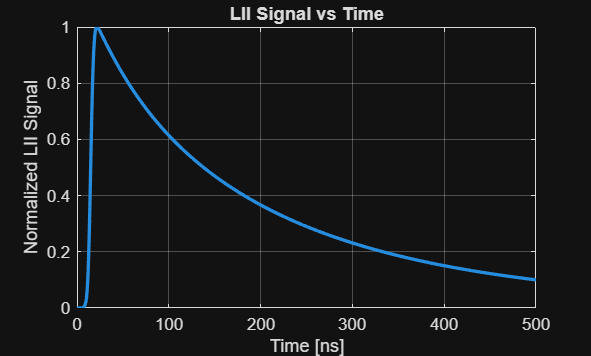

lambda_det = linspace(600e-7,620e-7,1000);

Rdet = 1;

S_LII = zeros(size(Tp));

for i = 1:length(Tp)

    Tp_i = Tp(i);

    Dp_i = Dp(i);

    Nc_i = ...
    (pi/6) .* ...
    Dp_i.^3 .* ...
    params.rho_s(Tp_i) .* ...
    params.NA ./ ...
    12.011;
    
    Xa_i = 1 - Nd(i)./(params.Xd .* Nc_i);
    
    Xa_i = max(0,min(1,Xa_i));

    Cabs_s_i = ...
    (1 - Xa_i) .* ...
    (pi^2 .* Dp_i.^3 ./ params.lambda_l) .* ...
    params.E_m .* ...
    params.Np;

    Cabs_a_i = ...
    Xa_i .* ...
    (pi^2 .* Dp_i.^3 ./ params.lambda_l) .* ...
    params.fa .* ...
    params.Ea_m .* ...
    params.Np;

    integrand = ...
    ((Cabs_s_i + Cabs_a_i) ./ ...
    (lambda_det.^5)) .* ...
    ( ...
    (Rdet ./ ...
    (exp((h*c) ./ ...
    (lambda_det .* params.kB .* Tp_i)) - 1)) ...
    - ...
    (Rdet ./ ...
    (exp((h*c) ./ ...
    (lambda_det .* params.kB .* params.Tg)) - 1)) ...
    );

    S_LII(i) = ...
    8 .* pi .* h .* c.^2 .* ...
    trapz(lambda_det,integrand);

end

S_LII = S_LII ./ max(S_LII);

figure

plot(t*1e9,S_LII,'LineWidth',2)

xlabel('Time [ns]')
ylabel('Normalized LII Signal')

title('LII Signal vs Time')

xlim([0 500])

grid on

Peak LII vs Fluence

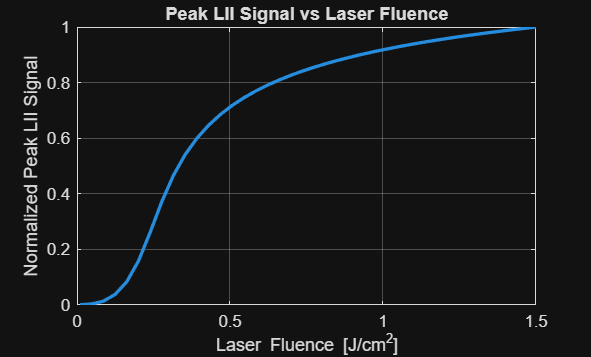

F_range = linspace(0.01,1.5,40);

peak_LII = zeros(size(F_range));

lambda_det = linspace(600e-7,620e-7,1000);

for j = 1:length(F_range)

    params_temp = params;

    params_temp.F = F_range(j);

    Nc0_temp = ...
    (pi/6) .* ...
    params_temp.Dp.^3 .* ...
    params_temp.rho_s(params_temp.Tg) .* ...
    params_temp.NA ./ ...
    12.011;
    
    Nd0_temp = ...
    params_temp.Xd .* Nc0_temp;
    
    Y0 = [params_temp.Tg;
          params_temp.Dp;
          Nd0_temp];

    [t_temp,Y_temp] = ode15s( ...
        @(t,Y) LII_odes(t,Y,params_temp), ...
        tspan, ...
        Y0, ...
        opts);

    Tp_temp = Y_temp(:,1);
    Dp_temp = Y_temp(:,2);
    Nd_temp = Y_temp(:,3);

    S_temp = zeros(size(Tp_temp));

    for i = 1:length(Tp_temp)

        Tp_i = Tp_temp(i);
        Dp_i = Dp_temp(i);
        

        Nc_i = ...
        (pi/6) .* ...
        Dp_i.^3 .* ...
        params_temp.rho_s(Tp_i) .* ...
        params_temp.NA ./ ...
        12.011;
        
        Xa = 1 - Nd_temp(i)./(params_temp.Xd .* Nc_i);
        
        Xa = max(0,min(1,Xa));

        Cabs_s_i = ...
        (1 - Xa) .* ...
        (pi^2 .* Dp_i.^3 ./ params_temp.lambda_l) .* ...
        params_temp.E_m .* ...
        params_temp.Np;

        Cabs_a_i = ...
        Xa .* ...
        (pi^2 .* Dp_i.^3 ./ params_temp.lambda_l) .* ...
        params_temp.fa .* ...
        params_temp.Ea_m .* ...
        params_temp.Np;

        integrand = ...
        ((Cabs_s_i + Cabs_a_i) ./ ...
        (lambda_det.^5)) .* ...
        ( ...
        (1 ./ ...
        (exp((h*c) ./ ...
        (lambda_det .* params_temp.kB .* Tp_i)) - 1)) ...
        - ...
        (1 ./ ...
        (exp((h*c) ./ ...
        (lambda_det .* params_temp.kB .* params_temp.Tg)) - 1)) ...
        );

        S_temp(i) = ...
        8 .* pi .* h .* c.^2 .* ...
        trapz(lambda_det,integrand);

    end

    peak_LII(j) = max(S_temp);

end
peak_LII = peak_LII ./ max(peak_LII);

figure

plot(F_range,peak_LII,'LineWidth',2)

xlabel('Laser Fluence [J/cm^2]')
ylabel('Normalized Peak LII Signal')

title('Peak LII Signal vs Laser Fluence')

grid on